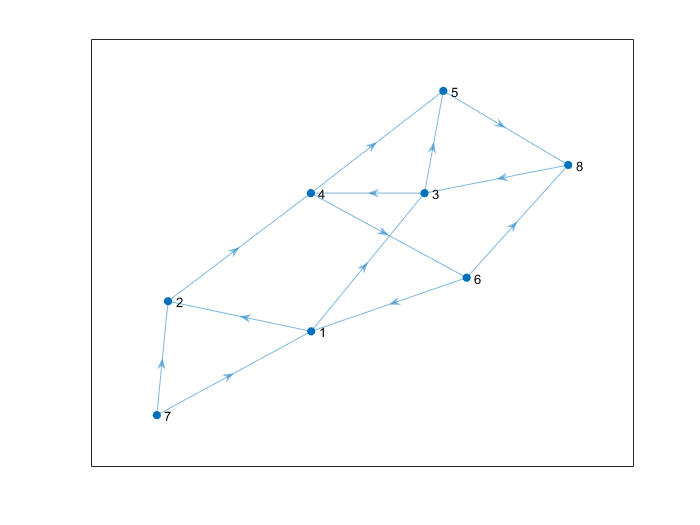

%博客案例一
s = [1 1 2 3 3 4 4 6 6 7 8 7 5];
t = [2 3 4 4 5 5 6 1 8 1 3 2 8];
G = digraph(s,t);
plot(G);

[P,d] = shortestpath(G,7,8)

P =      7     1     3     5     8


d = 4

edgepath =     11     2     5     8


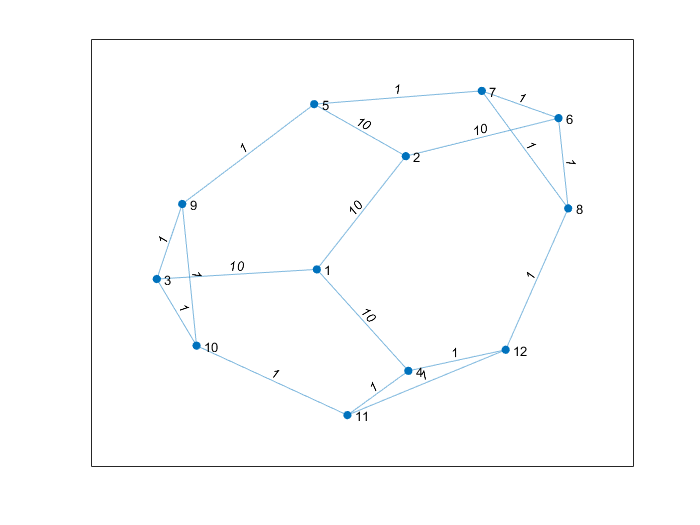

%博客案例二
s = [1 1 1 2 2 6 6 7 7 3 3 9 9 4 4 11 11 8];
t = [2 3 4 5 6 7 8 5 8 9 10 5 10 11 12 10 12 12];
weights = [10 10 10 10 10 1 1 1 1 1 1 1 1 1 1 1 1 1];
G = graph(s,t,weights);
plot(G,'EdgeLabel',G.Edges.Weight)

[P,d] = shortestpath(G,3,8)

P =      3     9     5     7     8


d = 4

%博客案例三
s = [1 1 1 1 1 2 2 7 7 9 3 3 1 4 10 8 4 5 6 8];
t = [2 3 4 5 7 6 7 5 9 6 6 10 10 10 11 11 8 8 11 9];
weights = [1 1 1 1 3 3 2 4 1 6 2 8 8 9 3 2 10 12 15 16];
G = graph(s,t,weights);

x = [0 0.5 -0.5 -0.5 0.5 0 1.5 0 2 -1.5 -2];
y = [0 0.5 0.5 -0.5 -0.5 2 0 -2 0 0 0];
p = plot(G,'XData',x,'YData',y,'EdgeLabel',G.Edges.Weight);
[path1,d] = shortestpath(G,6,8)

path1 =      6     3     1     4     8


d = 14

highlight(p,path1,'EdgeColor','g')
[path2,d] = shortestpath(G,6,8,'Method','unweighted')

path2 =      6     9     8


d = 2

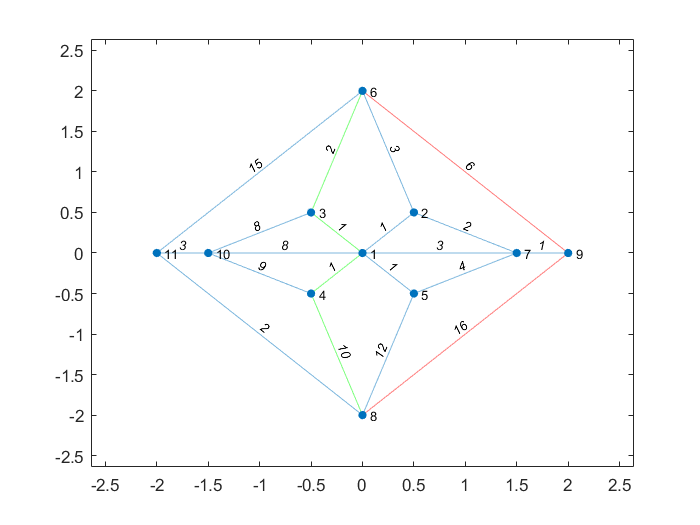

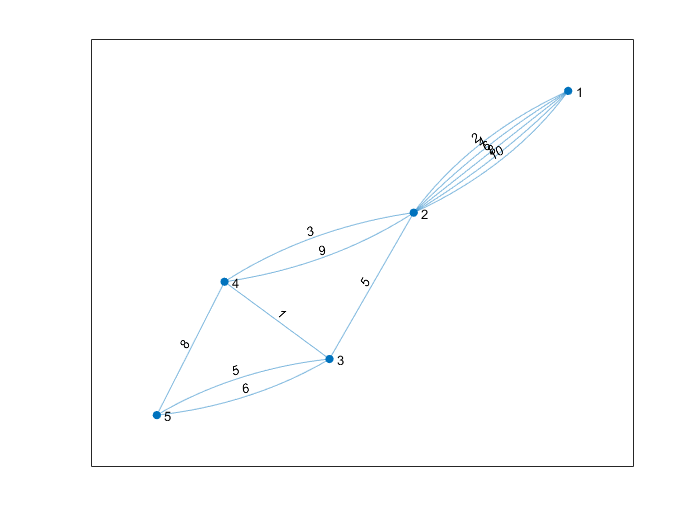

highlight(p,path2,'EdgeColor','r')